# Chapter 3

## Explanatory Data Analysis and Pivot Tables

Xt= readtable("Firm.xlsx", ReadRowNames=true)

Xt = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'M'} 

t1=summary(Xt(:,1:6))

t1 = struct with fields:
      Surname: [1×1 struct]
         Name: [1×1 struct]
       Gender: [1×1 struct]
    BirthDate: [1×1 struct]
    Education: [1×1 struct]
         Wage: [1×1 struct]


t2=summary(head(Xt,6))

t2 = struct with fields:
           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]


% Display the summaries in the command window
disp(t1);

      Surname: [1×1 struct]
         Name: [1×1 struct]
       Gender: [1×1 struct]
    BirthDate: [1×1 struct]
    Education: [1×1 struct]
         Wage: [1×1 struct]



disp(t2);

           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]



% Create a summary table for the entire dataset
summaryTable = summary(Xt);
disp(summaryTable);

           Surname: [1×1 struct]
              Name: [1×1 struct]
            Gender: [1×1 struct]
         BirthDate: [1×1 struct]
         Education: [1×1 struct]
              Wage: [1×1 struct]
     CommutingTime: [1×1 struct]
    SmartWorkHours: [1×1 struct]
         Seniority: [1×1 struct]



colors = categorical(["green" "blue" "red"])

colors = 1×3 categorical array
     green      blue      red 


disp(colors)

     green      blue      red 



% create a catagorical order for those who doesn't have manually
rankm= categorical(["first" "third" "second"],["first" "second" "third"])

rankm = 1×3 categorical array
     first      third      second 


% create a string array of length 10 named c
c= string(["School leaving certficate","High school graduate","Bachlor Degree", "Masters Degree"]);

% now convert the above c to ordinal catagorical
% Convert the string array to a categorical array with ordinal categories
cat = categorical(c, 'Ordinal', true);

levels=(["School leaving certficate","High school graduate","Bachlor Degree", "Masters Degree"])

levels = 1×4 string array
    "School leaving certficate"    "High school graduate"    "Bachlor Degree"    "Masters Degree"


cat2 = categorical(c,levels,Ordinal=true)

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


cat2 =addcats(cat2,"Primary School","Before","School leaving certficate")

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


cat2 = addcats(cat2,'Phd Degree','After','Masters Degree')

cat2 = 1×4 categorical array
     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 


% Display the updated categorical array
disp(cat2);

     School leaving certficate      High school graduate      Bachlor Degree      Masters Degree 



% define gender as nominal catagorical
Xt.Gender = categorical(Xt.Gender);
% define educational as ordinal catagory
Xt.Education= categorical(Xt.Education, Ordinal=true);

## Univariate Analysis of Categorical Variables

## frequency distribution


tabulate(Xt.Education)

  Value    Count   Percent
      A       24     22.43%
      B       37     34.58%
      C       46     42.99%



tabulate(Xt.Gender)

  Value    Count   Percent
      F       46     42.99%
      M       61     57.01%



tabulate(Xt.Wage)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5        0      0.00%
      6        0      0.00%
      7        0      0.00%
      8        0      0.00%
      9        0      0.00%
     10        0      0.00%
     11        0      0.00%
     12        0      0.00%
     13        0      0.00%
     14        0      0.00%
     15        0      0.00%
     16        0      0.00%
     17        0      0.00%
     18        0      0.00%
     19        0      0.00%
     20        0      0.00%
     21        0      0.00%
     22        0      0.00%
     23        0      0.00%
     24        0      0.00%
     25        0      0.00%
     26        0      0.00%
     27        0      0.00%
     28        0      0.00%
     29        0      0.00%
     30        0      0.00%
     31        0      0.00%
     32        0      0.00%
     33        0      0.00%
     34        0      0.00%
     35        0     


tabulate(Xt.Seniority)

  Value    Count   Percent
      1        3      2.80%
      2        9      8.41%
      3        3      2.80%
      4        3      2.80%
      5        4      3.74%
      6        2      1.87%
      7        5      4.67%
      8        4      3.74%
      9        3      2.80%
     10        4      3.74%
     11        5      4.67%
     12        4      3.74%
     13        4      3.74%
     14        5      4.67%
     15        4      3.74%
     16        7      6.54%
     17        3      2.80%
     18        2      1.87%
     19        4      3.74%
     20        2      1.87%
     21        0      0.00%
     22        1      0.93%
     23        1      0.93%
     24        2      1.87%
     25        1      0.93%
     26        2      1.87%
     27        0      0.00%
     28        3      2.80%
     29        1      0.93%
     30        2      1.87%
     31        5      4.67%
     32        2      1.87%
     33        1      0.93%
     34        1      0.93%
     35        1     

mode(Xt.Gender)

ans = categorical
     M 


tabulate(Xt.Gender)

  Value    Count   Percent
      F       46     42.99%
      M       61     57.01%


median(Xt.Education)

ans = categorical
     B 


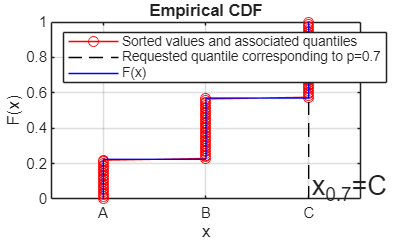

ans = struct with fields:
    quantile: 'C'


% COMPUte and display in plot the 0.7 quantile for the ordinal catagorical
% variable education
GUIquantile(Xt.Education,0.7)

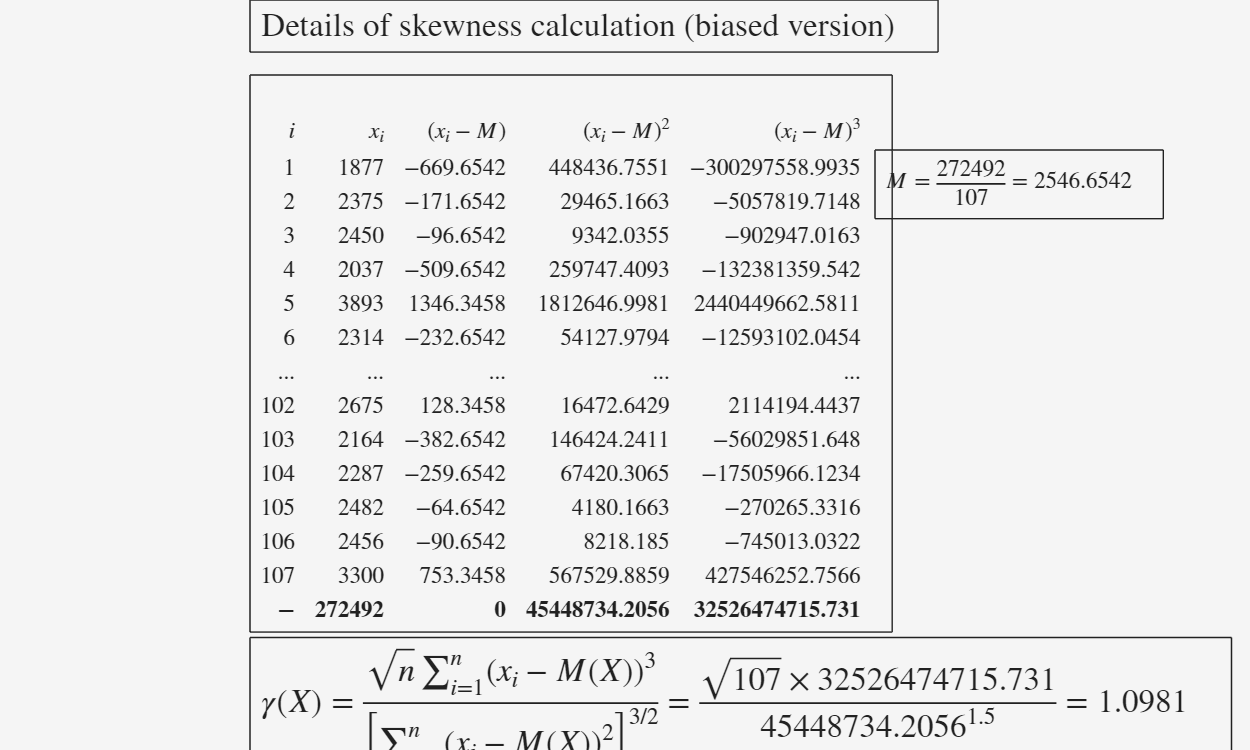

ans = struct with fields:
     data: [108×5 table]
    gamma: 1.0981


GUIskewness(Xt.Wage)

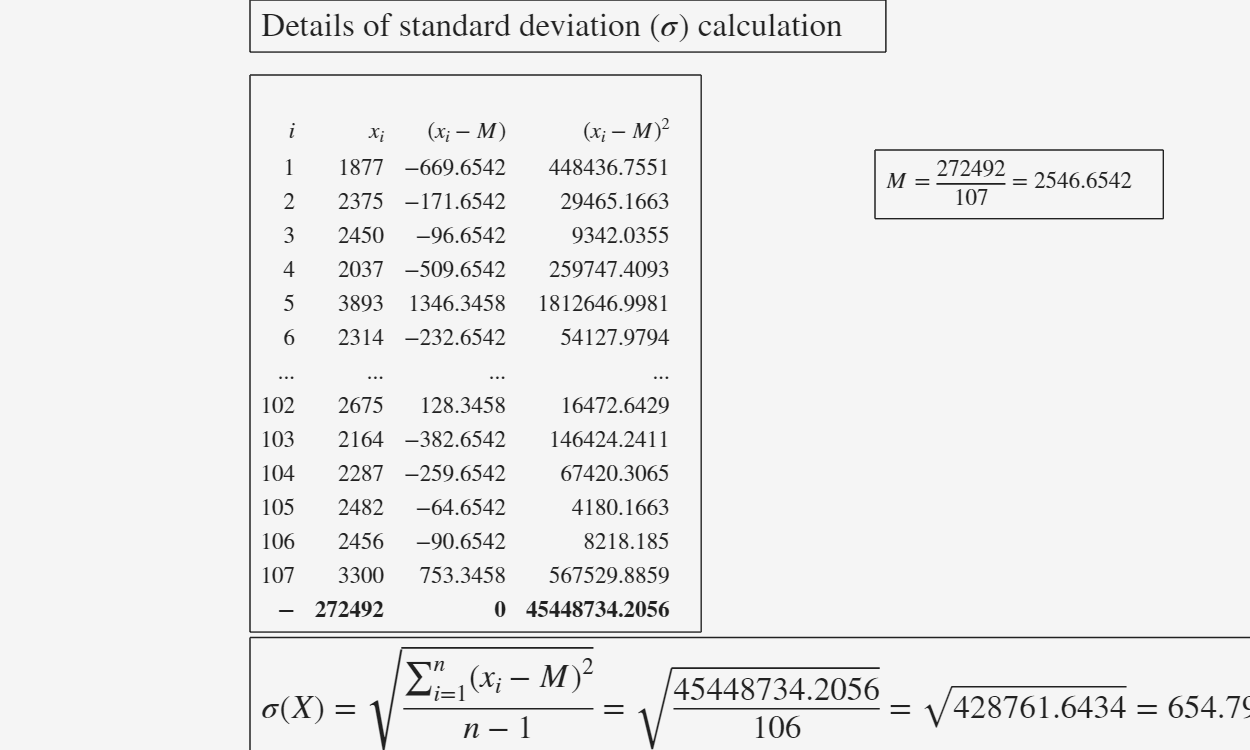

ans = struct with fields:
    data: [108×4 table]
     std: 654.7989


GUIstd(Xt.Wage)

Xdg=([Xt.Wage Xt.CommutingTime Xt.SmartWorkHours  Xt.Seniority])

Xdg =         1877          27          10          11
        2375          35          12           8
        2450          39          16          11
        2037          16           6           7
        3893          23           8          30
        2314          29          10          23
        1893          29           6          12
        2443          16           6          28
        2016          19           4           2
        1635          45          16           2
        2593          15           4          13
        3370          26          12          16
        2141          27          10           6
        4354          21          10          40
        2226          47          14          11


% calculate the mean and median of all four variable of Xdg
meanvalue= mean(Xdg)

meanvalue = 1.0e+03 *

    2.5467    0.0224    0.0076    0.0153


medianv=median(Xdg)

medianv =         2423          20           6          14


Xdq =[ "Wage" "CommutingTime"  "SmartWorkHours"  "Seniority" ]

Xdq = 1×4 string array
    "Wage"    "CommutingTime"    "SmartWorkHours"    "Seniority"


Xdq2=Xt(:,Xdq)

Xdq2 = 107×4 table
             Wage    CommutingTime    SmartWorkHours    Seniority
             ____    _____________    ______________    _________

    P0211    1877         27                10             11    
    P0212    2375         35                12              8    
    P0213    2450         39                16             11    
    P0214    2037         16                 6              7    
    P0215    3893         23                 8             30    
    P0216    2314         29                10             23    
    P0217    1893         29                 6             12    
    P0218    2443         16                 6             28    
    P0219    2016         19   

mean(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    2546.7       22.355            7.5888         15.262  


median(Xdq2)

ans = 1×4 table
    Wage    CommutingTime    SmartWorkHours    Seniority
    ____    _____________    ______________    _________

    2423         20                6              14    


std(Xdg)

ans =   654.7989    8.8651    3.2707   10.5234


std(Xdq2)

ans = 1×4 table
    Wage     CommutingTime    SmartWorkHours    Seniority
    _____    _____________    ______________    _________

    654.8       8.8651            3.2707         10.523  


% calculate coefficient variation 
cv = std(Xdg) ./ meanvalue * 100; % Calculate coefficient of variation
disp('Coefficient of Variation:');

Coefficient of Variation:


disp(cv);

   25.7121   39.6557   43.0986   68.9532



% compute skewness
skewness(Xdg,0)

ans =     1.1138    0.9890    0.8261    0.6682


skewness(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    1.0981       0.97506          0.81443         0.65881 



% compute kurtosis
kurtosis(Xdg)

ans =     3.7885    3.7216    2.9839    2.5635


kurtosis(Xdq2)

ans = 1×4 table
     Wage     CommutingTime    SmartWorkHours    Seniority
    ______    _____________    ______________    _________

    3.7885       3.7216            2.9839         2.5635  


## Univariate plots for Categorical or Quantitative Data

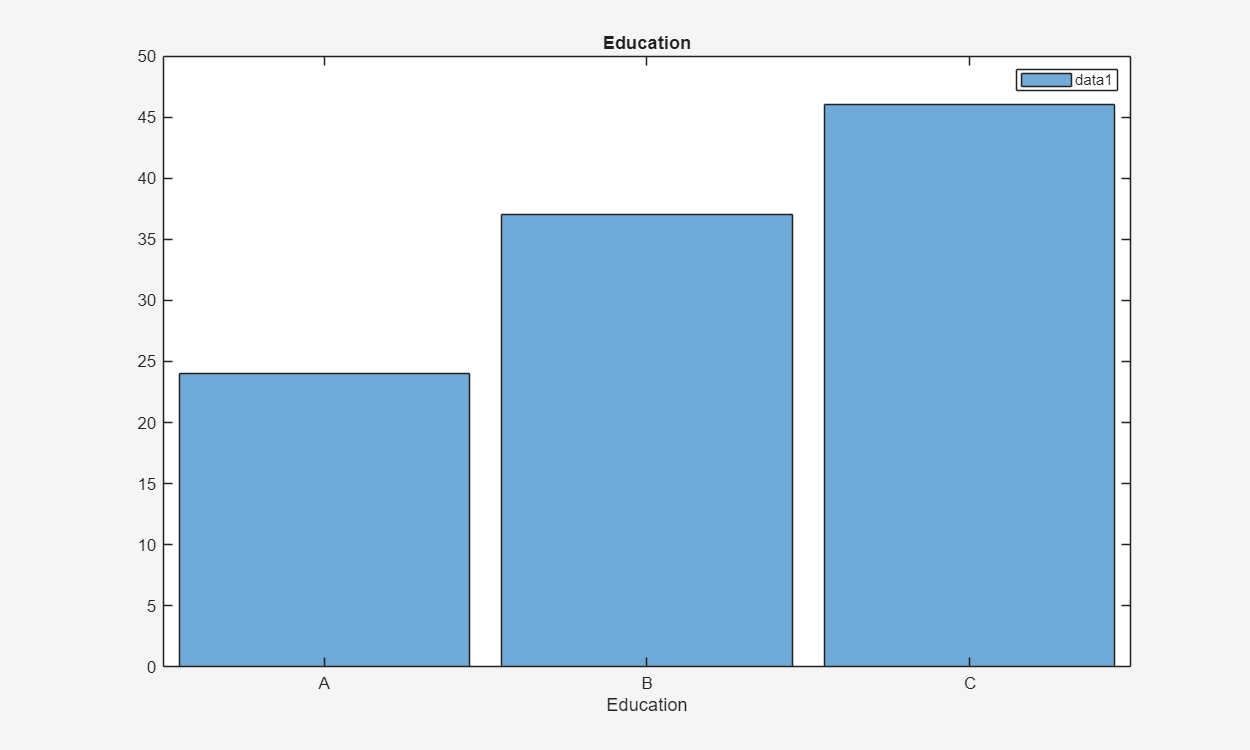

histogram(Xt.Education);
xlabel("Education");
title("Education");
legend("show");

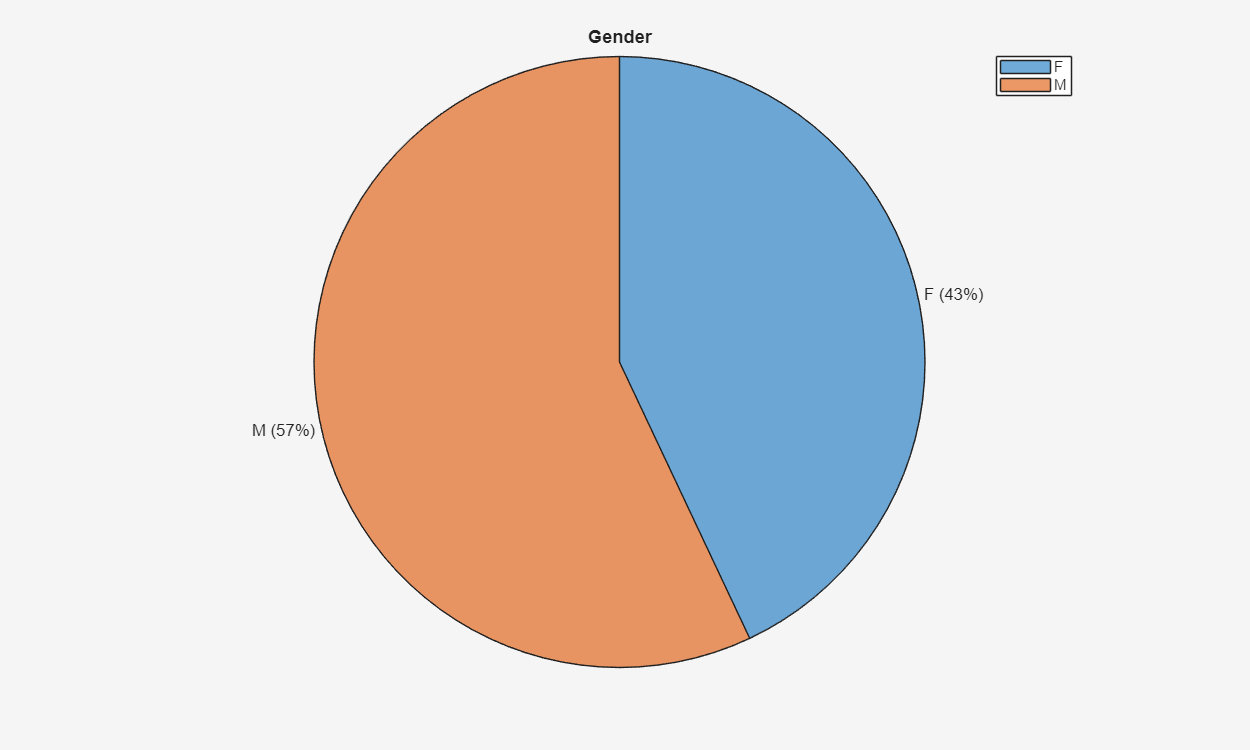

piechart(Xt.Gender);
title("Gender");
legend("show");

rng(100)
n=1000

n = 1000

x=randn(n,1)

x =     0.1609
   -0.6151
   -0.2390
    0.6150
   -0.9014
    0.3481
    0.9480
   -1.7299
    0.0971
    1.3786
   -0.9167
   -1.0357
   -0.2241
    2.7022
    0.5202


bins=[-inf;-2;0;1.5;inf]

bins =       -Inf
   -2.0000
         0
    1.5000
       Inf


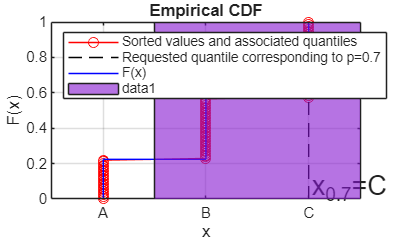

h =   Histogram with properties:

             Data: 1000
           Values: [0 0 0 1]
          NumBins: 4
         BinEdges: [-Inf -2 0 1.5000 Inf]
         BinWidth: 'nonuniform'
        BinLimits: [-Inf Inf]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0.1294 0.1294 0.1294]

  Show all properties


h=histogram(n,bins)